# ACML Homework: Neural Networks

#### Before reading the code

The code has been seperated into two parts:

1. The first part is using the optimal data and parameters to train the model, which can generate the same output as input eight examples. The test results are in 1.4.2;

2. The second part includes multiple experiments to test the influence of different input data and hyperparameters, which leads to the final setting of model in the first part.

## First Part - Train the Model with Optimal Parameter for Testing

### 1.1 Data Generation

%generate learning examples
X = eye(8);

%prepare training data
random_indices = randperm(8, 8)

random_indices =      7     4     1     2     5     8     3     6


X_train = X(random_indices, :)

X_train =      0     0     0     0     0     0     1     0
     0     0     0     1     0     0     0     0
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     1
     0     0     1     0     0     0     0     0
     0     0     0     0     0     1     0     0


Y_train = X_train;
%add the bias term for input layer
one_col = ones(size(X_train, 1), 1);
X_train_bias = [one_col, X_train];

### 1.2 Parameter Defination

%define the size of three layers
num_layer1 = 8;
num_layer2 = 3;
num_layer3 = 8;

%define hyperparameters learnt from second part
%regularization coefficient
lambda = 0;
%learning rate
alpha = 0.7;
%iteration for model to converge
max_iteration = 8000; 
%threshold for binary output
threshold = 0.5; 
%randomly initalize weight(Theta) between (-t, t)
t = 0.5;
Theta1 = rand(num_layer2, num_layer1+1)*t*2 - t;
Theta2 = rand(num_layer3, num_layer2+1)*t*2 - t;

### 1.3 Model Training

%create a loop to update the weight(Theta) several times, monitor the error
%between model hypothesis and expected output to see when the model converges

%create an empty array for visualization of error(MSE-mean square error)
MSE_all= [];

#### 1.3.1 Feedforward

for i = 1:max_iteration

    %from layer 1 to layer 2
    z2 = X_train_bias * Theta1';
    %activations for layer2, sigmoid function is defined the another file
    a2 = sigmoid(z2); 

    %from layer 2 to layer 3
    %add bias term in the hidden layer
    one_col = ones(size(a2, 1), 1); 
    a2_bias = [one_col, a2];

    z3 = a2_bias * Theta2';
    %activations for layer3
    a3 = sigmoid(z3);

#### 1.3.2 Backpropagation

    %compute the "error term" in layer3 and layer2
    %layer3
    Detrivate_g_z3 = a3.*(ones(size(a3))-a3);
    s3 = (a3 - Y_train).*Detrivate_g_z3;

    %layer2
    Detrivate_g_z2 = a2.*(ones(size(a2))-a2);
    s2 = (s3*Theta2(:,2:end)).*Detrivate_g_z2;
    
    %compute partial derivatives for update the weight(Theta)
    %set Delta and D_gradient to zero with the same size as the weight(Theta)
    Delta2 = zeros(num_layer3, num_layer2+1);
    Delta1 = zeros(num_layer2, num_layer1+1);
    D_gradient2 = zeros(num_layer3, num_layer2+1);
    D_gradient1 = zeros(num_layer2, num_layer1+1);

    %from layer3 to layer2
    Delta2(:,2:end) = Delta2(:,2:end) + s3'*a2;
    Delta2(:,1) = Delta2(:,1) + (s3(1,:))';
    %from layer2 to layer1
    Delta1(:,2:end) = Delta1(:,2:end) + s2'*X_train;
    Delta1(:,1) = Delta1(:,1) + (s2(1,:))';
    
    %add regularization term to partial derivatives, but not on the bias term 
    %from layer3 to layer2
    D_gradient2(:,2:end) = (1/size(X_train,1))*(Delta2(:,2:end) + (lambda*Theta2(:,2:end)));
    D_gradient2(:,1) = (1/size(X_train,1))*Delta2(:,1);
    %from layer2 to layer1
    D_gradient1(:,2:end) = (1/size(X_train,1))*(Delta1(:,2:end) + (lambda*Theta1(:,2:end)));
    D_gradient1(:,1) = (1/size(X_train,1))*Delta1(:,1);
    
    %update the weight(Theta) between layers
    Theta2 = Theta2 - alpha*D_gradient2;
    Theta1 = Theta1 - alpha*D_gradient1;

#### 1.3.3 Monitor Model Performance

    %moniter the error between hypothesis and expected output every 100 iterations
    %to check if the model converges using MSE(mean square error)

    evaluation_interval = 100;
    if mod(i, evaluation_interval) == 0

        %compute MSE
        MSE = (1/size(Y_train, 1))*sum(sum((a3-Y_train).^2));

        %store the MSE for plot later
        MSE_all = [MSE_all, MSE];

        fprintf('Iteration %d: MSE = %.4f\n', i, MSE);
        disp(' ');
    end
end

Iteration 100: MSE = 0.8926


Iteration 200: MSE = 0.8655


Iteration 300: MSE = 0.8276


Iteration 400: MSE = 0.8043


Iteration 500: MSE = 0.7892


Iteration 600: MSE = 0.7732


Iteration 700: MSE = 0.7514


Iteration 800: MSE = 0.7180


Iteration 900: MSE = 0.6692


Iteration 1000: MSE = 0.6146


Iteration 1100: MSE = 0.5671


Iteration 1200: MSE = 0.5306


Iteration 1300: MSE = 0.5038


Iteration 1400: MSE = 0.4833


Iteration 1500: MSE = 0.4664


Iteration 1600: MSE = 0.4513


Iteration 1700: MSE = 0.4372


Iteration 1800: MSE = 0.4240


Iteration 1900: MSE = 0.4116


Iteration 2000: MSE = 0.3999


Iteration 2100: MSE = 0.3884


Iteration 2200: MSE = 0.3766


Iteration 2300: MSE = 0.3637


Iteration 2400: MSE = 0.3493


Iteration 2500: MSE = 0.3334


Iteration 2600: MSE = 0.3166


Iteration 2700: MSE = 0.3000


Iteration 2800: MSE = 0.2847


Iteration 2900: MSE = 0.2709


Iteration 3000: MSE = 0.2589


Iteration 3100: MSE = 0.2484


Iteration 3200: MSE = 0.2393


Iteration 3300: MSE = 0.2313


Iteration 3400: MSE = 0.2244


Iteration 3500: MSE = 0.2182


Iteration 3600: MSE = 0.2127


Iteration 3700: MSE = 0.2078


Iteration 3800: MSE = 0.2033


Iteration 3900: MSE = 0.1991


Iteration 4000: MSE = 0.1953


Iteration 4100: MSE = 0.1917


Iteration 4200: MSE = 0.1883


Iteration 4300: MSE = 0.1851


Iteration 4400: MSE = 0.1821


Iteration 4500: MSE = 0.1791


Iteration 4600: MSE = 0.1764


Iteration 4700: MSE = 0.1737


Iteration 4800: MSE = 0.1710


Iteration 4900: MSE = 0.1685


Iteration 5000: MSE = 0.1660


Iteration 5100: MSE = 0.1636


Iteration 5200: MSE = 0.1613


Iteration 5300: MSE = 0.1590


Iteration 5400: MSE = 0.1568


Iteration 5500: MSE = 0.1546


Iteration 5600: MSE = 0.1524


Iteration 5700: MSE = 0.1503


Iteration 5800: MSE = 0.1482


Iteration 5900: MSE = 0.1462


Iteration 6000: MSE = 0.1442


Iteration 6100: MSE = 0.1423


Iteration 6200: MSE = 0.1404


Iteration 6300: MSE = 0.1385


Iteration 6400: MSE = 0.1367


Iteration 6500: MSE = 0.1349


Iteration 6600: MSE = 0.1331


Iteration 6700: MSE = 0.1314


Iteration 6800: MSE = 0.1297


Iteration 6900: MSE = 0.1281


Iteration 7000: MSE = 0.1264


Iteration 7100: MSE = 0.1248


Iteration 7200: MSE = 0.1233


Iteration 7300: MSE = 0.1217


Iteration 7400: MSE = 0.1202


Iteration 7500: MSE = 0.1187


Iteration 7600: MSE = 0.1173


Iteration 7700: MSE = 0.1159


Iteration 7800: MSE = 0.1145


Iteration 7900: MSE = 0.1131


Iteration 8000: MSE = 0.1118


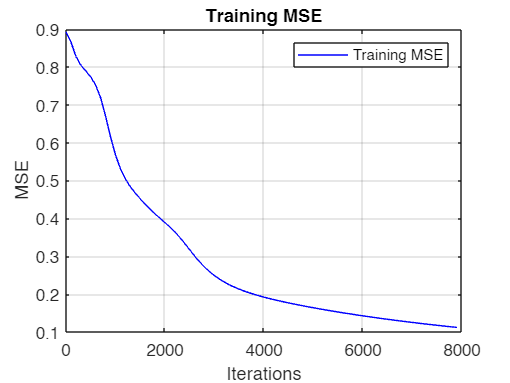


%plot the tendency of MSE
iterations = 1:evaluation_interval:max_iteration; %set X

figure;
plot(iterations, MSE_all, 'b', 'DisplayName', 'Training MSE');
title('Training MSE');
xlabel('Iterations');
ylabel('MSE');
legend;
grid on;

### 1.4 Data Testing

#### 1.4.1 Feedforward

%test on the same dataset using optimal weights
%add bias term

random_indices_test = randperm(8, 8)

random_indices_test =      7     3     1     5     8     6     2     4


X_test = X(random_indices_test, :)

X_test =      0     0     0     0     0     0     1     0
     0     0     1     0     0     0     0     0
     1     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     1
     0     0     0     0     0     1     0     0
     0     1     0     0     0     0     0     0
     0     0     0     1     0     0     0     0



one_col = ones(size(X_test, 1), 1);
X_test_bias = [one_col, X_test];

%feedforward
%layer1 to layer2
z2 = X_test_bias * Theta1';
a2 = sigmoid(z2);

%layer2 to layer3
%add bias term
one_col = ones(size(a2, 1), 1);
a2_bias = [one_col, a2];

z3 = a2_bias * Theta2';
a3 = sigmoid(z3);


#### 1.4.2 Output Generation

%convert probability into binary results
output_labels = a3 >= threshold

output_labels = 8×8 logical array
   0   0   0   0   0   0   1   0
   0   0   1   0   0   0   0   0
   1   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   0
   0   0   0   0   0   0   0   1
   0   0   0   0   0   1   0   0
   0   1   0   0   0   0   0   0
   0   0   0   1   0   0   0   0



%measure the accuracy
sum_total = size(X_test, 1);
m = all(X_test == output_labels, 2);
rowMatches = sum(m)

rowMatches = 8

accuracy = rowMatches/sum_total

accuracy = 1

#### 1.4.3 Final weights and activations of the model

%display final learnt weight and activations
disp('a3 =');

a3 =


disp(a3);

    0.0257    0.0211    0.0322    0.0268    0.0266    0.0285    0.9806    0.0255
    0.0208    0.0001    0.6131    0.0023    0.0426    0.1400    0.0000    0.0001
    0.8357    0.1079    0.2365    0.0000    0.0533    0.0849    0.0081    0.0000
    0.0998    0.0000    0.2346    0.1135    0.8852    0.0072    0.0717    0.0001
    0.0000    0.0098    0.0379    0.1295    0.0001    0.2561    0.0540    0.8849
    0.0015    0.1498    0.1972    0.0002    0.0000    0.6561    0.0000    0.0765
    0.1661    0.7776    0.0802    0.0000    0.0004    0.2782    0.0518    0.0081
    0.0000    0.0000    0.2042    0.8644    0.0344    0.0440    0.0005    0.0622




disp('a2 =');

a2 =


disp(a2);

    0.0815    0.0603    0.0714
    0.9911    0.6847    0.9447
    0.4456    0.0110    0.9620
    0.8374    0.0154    0.2175
    0.0297    0.9173    0.1132
    0.2472    0.9877    0.9741
    0.0067    0.3023    0.8391
    0.7910    0.8663    0.0072




disp('Theta2 =');

Theta2 =


disp(Theta2)

   -3.5445    0.3843   -8.3105    5.2924
   -3.3020  -10.6217   -1.8506    6.1787
   -3.7414    2.6800    0.2895    1.4263
   -3.4418    3.8892    2.6329   -8.7858
   -3.6334    7.5882   -6.5606   -2.6538
   -3.6769   -2.1453    2.6301    2.3152
    5.5442   -7.6825   -8.0396   -7.1129
   -3.2122   -6.3914    6.4475   -4.1752




disp('Theta1 =');

Theta1 =


disp(Theta1)

   -0.9696    0.7513   -4.0297    5.6791    2.3006    2.6084   -0.1442   -1.4525   -2.5157
   -1.3021   -3.1995    0.4660    2.0777    3.1707   -2.8533    5.6871   -1.4436    3.7084
   -1.5182    4.7495    3.1697    4.3570   -3.4055    0.2379    5.1472   -1.0467   -0.5405



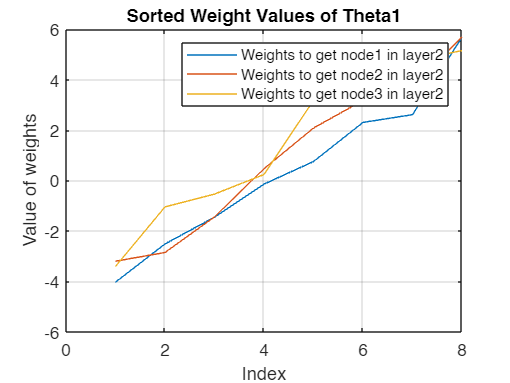


%plot weights(Theta1) to see the relationship
Theta1_1 = sort(Theta1(1,2:end));
Theta1_2 = sort(Theta1(2,2:end));
Theta1_3 = sort(Theta1(3,2:end));
plot(Theta1_1,'DisplayName', 'Weights to get node1 in layer2')
hold on
plot(Theta1_2,'DisplayName', 'Weights to get node2 in layer2')
plot(Theta1_3,'DisplayName', 'Weights to get node3 in layer2')

xlabel('Index');
ylabel('Value of weights');
title('Sorted Weight Values of Theta1');

grid on;
legend('show')
hold off

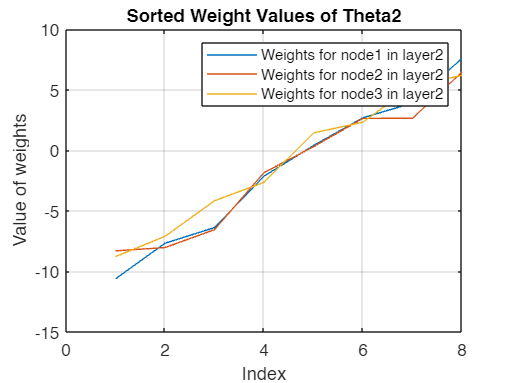


%plot weights(Theta2) to see the relationship
Theta2_1 = sort(Theta2(:,2));
Theta2_2 = sort(Theta2(:,3));
Theta2_3 = sort(Theta2(:,4));
plot(Theta2_1,'DisplayName', 'Weights for node1 in layer2')
hold on
plot(Theta2_2,'DisplayName', 'Weights for node2 in layer2')
plot(Theta2_3,'DisplayName', 'Weights for node3 in layer2')

xlabel('Index');
ylabel('Value of weights');
title('Sorted Weight Values of Theta2');

grid on;
legend('show')
hold off

## Second Part - Test the Influence of Input Data and Hyperparameters

### 2.1 Parameter Testing

#### 2.1.1 Regularization coefficient : 

#### lambda = 0.1

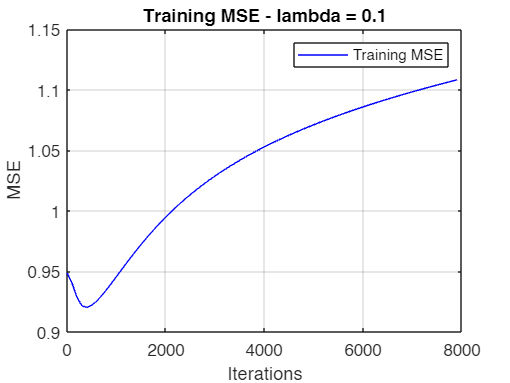

%regularization coefficient
lambda = 0.1;

%randomly initalize weight(Theta) between (-t, t)
t = 0.5;
Theta1 = rand(num_layer2, num_layer1+1)*t*2 - t;
Theta2 = rand(num_layer3, num_layer2+1)*t*2 - t;

%model training
%create an empty array for visualization of error(MSE-mean square error)
MSE_all= [];

for i = 1:max_iteration
    %feedforward
    %from layer 1 to layer 2
    z2 = X_train_bias * Theta1';
    a2 = sigmoid(z2); 

    %from layer 2 to layer 3
    one_col = ones(size(a2, 1), 1); 
    a2_bias = [one_col, a2];
    z3 = a2_bias * Theta2';
    a3 = sigmoid(z3);

    %backpropagation
    %layer3
    Detrivate_g_z3 = a3.*(ones(size(a3))-a3);
    s3 = (a3 - Y_train).*Detrivate_g_z3;
    %layer2
    Detrivate_g_z2 = a2.*(ones(size(a2))-a2);
    s2 = (s3*Theta2(:,2:end)).*Detrivate_g_z2;
    
    %compute partial derivatives for update the weight(Theta)
    Delta2 = zeros(num_layer3, num_layer2+1);
    Delta1 = zeros(num_layer2, num_layer1+1);
    D_gradient2 = zeros(num_layer3, num_layer2+1);
    D_gradient1 = zeros(num_layer2, num_layer1+1);

    %from layer3 to layer2
    Delta2(:,2:end) = Delta2(:,2:end) + s3'*a2;
    Delta2(:,1) = Delta2(:,1) + (s3(1,:))';
    %from layer2 to layer1
    Delta1(:,2:end) = Delta1(:,2:end) + s2'*X_train;
    Delta1(:,1) = Delta1(:,1) + (s2(1,:))';
    
    %add regularization term to partial derivatives, but not on the bias term 
    %from layer3 to layer2
    D_gradient2(:,2:end) = (1/size(X_train,1))*(Delta2(:,2:end) + (lambda*Theta2(:,2:end)));
    D_gradient2(:,1) = (1/size(X_train,1)).*Delta2(:,1);
    %from layer2 to layer1
    D_gradient1(:,2:end) = (1/size(X_train,1))*(Delta1(:,2:end) + (lambda*Theta1(:,2:end)));
    D_gradient1(:,1) = (1/size(X_train,1))*Delta1(:,1);
    
    %update the weight(Theta) between layers
    Theta2 = Theta2 - alpha*D_gradient2;
    Theta1 = Theta1 - alpha*D_gradient1;

    %moniter the error between hypothesis and expected output every 100 iterations
    evaluation_interval = 100;
    if mod(i, evaluation_interval) == 0
        %compute MSE
        MSE = (1/size(Y_train, 1))*sum(sum((a3-Y_train).^2));
        %store the MSE for plot later
        MSE_all = [MSE_all, MSE];
    end
end

%plot the tendency of MSE
iterations = 1:evaluation_interval:max_iteration; %set X
figure;
plot(iterations, MSE_all, 'b', 'DisplayName', 'Training MSE');
title('Training MSE - lambda = 0.1');
xlabel('Iterations');
ylabel('MSE');
legend;
grid on;



%test the examples

%feedforward
%layer1 to layer2
z2 = X_test_bias * Theta1';
a2 = sigmoid(z2);
%layer2 to layer3
one_col = ones(size(a2, 1), 1);
a2_bias = [one_col, a2];
z3 = a2_bias * Theta2';
a3 = sigmoid(z3);

%convert probability into binary results
output_labels = a3 >= threshold

output_labels = 8×8 logical array
   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   1   0



%measure the accuracy
sum_total = size(X_test, 1);
m = all(X_test == output_labels, 2);
rowMatches = sum(m)

rowMatches = 1

accuracy = rowMatches/sum_total

accuracy = 0.1250

#### lambda = 0.01

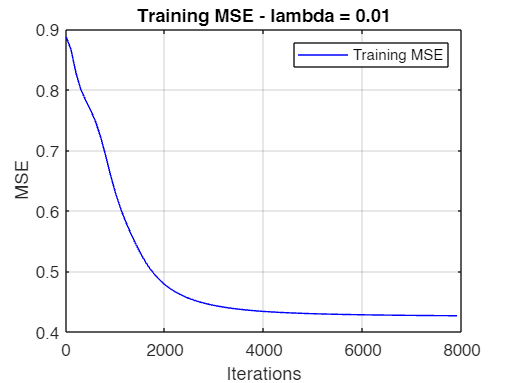

%regularization coefficient
lambda = 0.01;

%randomly initalize weight(Theta) between (-t, t)
t = 0.5;
Theta1 = rand(num_layer2, num_layer1+1)*t*2 - t;
Theta2 = rand(num_layer3, num_layer2+1)*t*2 - t;

%model training
%create an empty array for visualization of error(MSE-mean square error)
MSE_all= [];

for i = 1:max_iteration
    %feedforward
    %from layer 1 to layer 2
    z2 = X_train_bias * Theta1';
    a2 = sigmoid(z2); 

    %from layer 2 to layer 3
    one_col = ones(size(a2, 1), 1); 
    a2_bias = [one_col, a2];
    z3 = a2_bias * Theta2';
    a3 = sigmoid(z3);

    %backpropagation
    %layer3
    Detrivate_g_z3 = a3.*(ones(size(a3))-a3);
    s3 = (a3 - Y_train).*Detrivate_g_z3;
    %layer2
    Detrivate_g_z2 = a2.*(ones(size(a2))-a2);
    s2 = (s3*Theta2(:,2:end)).*Detrivate_g_z2;
    
    %compute partial derivatives for update the weight(Theta)
    Delta2 = zeros(num_layer3, num_layer2+1);
    Delta1 = zeros(num_layer2, num_layer1+1);
    D_gradient2 = zeros(num_layer3, num_layer2+1);
    D_gradient1 = zeros(num_layer2, num_layer1+1);

    %from layer3 to layer2
    Delta2(:,2:end) = Delta2(:,2:end) + s3'*a2;
    Delta2(:,1) = Delta2(:,1) + (s3(1,:))';
    %from layer2 to layer1
    Delta1(:,2:end) = Delta1(:,2:end) + s2'*X_train;
    Delta1(:,1) = Delta1(:,1) + (s2(1,:))';
    
    %add regularization term to partial derivatives, but not on the bias term 
    %from layer3 to layer2
    D_gradient2(:,2:end) = (1/size(X_train,1))*(Delta2(:,2:end) + (lambda*Theta2(:,2:end)));
    D_gradient2(:,1) = (1/size(X_train,1)).*Delta2(:,1);
    %from layer2 to layer1
    D_gradient1(:,2:end) = (1/size(X_train,1))*(Delta1(:,2:end) + (lambda*Theta1(:,2:end)));
    D_gradient1(:,1) = (1/size(X_train,1))*Delta1(:,1);
    
    %update the weight(Theta) between layers
    Theta2 = Theta2 - alpha*D_gradient2;
    Theta1 = Theta1 - alpha*D_gradient1;

    %moniter the error between hypothesis and expected output every 100 iterations
    evaluation_interval = 100;
    if mod(i, evaluation_interval) == 0
        %compute MSE
        MSE = (1/size(Y_train, 1))*sum(sum((a3-Y_train).^2));
        %store the MSE for plot later
        MSE_all = [MSE_all, MSE];
    end
end

%plot the tendency of MSE
iterations = 1:evaluation_interval:max_iteration; %set X
figure;
plot(iterations, MSE_all, 'b', 'DisplayName', 'Training MSE');
title('Training MSE - lambda = 0.01');
xlabel('Iterations');
ylabel('MSE');
legend;
grid on;



%test the examples

%feedforward
%layer1 to layer2
z2 = X_test_bias * Theta1';
a2 = sigmoid(z2);
%layer2 to layer3
one_col = ones(size(a2, 1), 1);
a2_bias = [one_col, a2];
z3 = a2_bias * Theta2';
a3 = sigmoid(z3);

%convert probability into binary results
output_labels = a3 >= threshold

output_labels = 8×8 logical array
   0   0   0   0   0   0   1   0
   0   0   1   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   1   0   0
   0   1   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



%measure the accuracy
sum_total = size(X_test, 1);
m = all(X_test == output_labels, 2);
rowMatches = sum(m)

rowMatches = 5

accuracy = rowMatches/sum_total

accuracy = 0.6250

#### 2.1.2 Learning rate 

#### alpha = 0.1

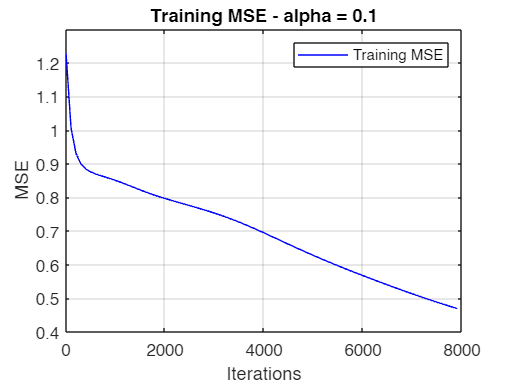

%learning rate
alpha = 0.1;

%reset the optimal regularization coefficient
lambda = 0;

%randomly initalize weight(Theta) between (-t, t)
t = 0.5;
Theta1 = rand(num_layer2, num_layer1+1)*t*2 - t;
Theta2 = rand(num_layer3, num_layer2+1)*t*2 - t;

%model training
%create an empty array for visualization of error(MSE-mean square error)
MSE_all= [];

for i = 1:max_iteration
    %feedforward
    %from layer 1 to layer 2
    z2 = X_train_bias * Theta1';
    a2 = sigmoid(z2); 

    %from layer 2 to layer 3
    one_col = ones(size(a2, 1), 1); 
    a2_bias = [one_col, a2];
    z3 = a2_bias * Theta2';
    a3 = sigmoid(z3);

    %backpropagation
    %layer3
    Detrivate_g_z3 = a3.*(ones(size(a3))-a3);
    s3 = (a3 - Y_train).*Detrivate_g_z3;
    %layer2
    Detrivate_g_z2 = a2.*(ones(size(a2))-a2);
    s2 = (s3*Theta2(:,2:end)).*Detrivate_g_z2;
    
    %compute partial derivatives for update the weight(Theta)
    Delta2 = zeros(num_layer3, num_layer2+1);
    Delta1 = zeros(num_layer2, num_layer1+1);
    D_gradient2 = zeros(num_layer3, num_layer2+1);
    D_gradient1 = zeros(num_layer2, num_layer1+1);

    %from layer3 to layer2
    Delta2(:,2:end) = Delta2(:,2:end) + s3'*a2;
    Delta2(:,1) = Delta2(:,1) + (s3(1,:))';
    %from layer2 to layer1
    Delta1(:,2:end) = Delta1(:,2:end) + s2'*X_train;
    Delta1(:,1) = Delta1(:,1) + (s2(1,:))';
    
    %add regularization term to partial derivatives, but not on the bias term 
    %from layer3 to layer2
    D_gradient2(:,2:end) = (1/size(X_train,1))*(Delta2(:,2:end) + (lambda*Theta2(:,2:end)));
    D_gradient2(:,1) = (1/size(X_train,1)).*Delta2(:,1);
    %from layer2 to layer1
    D_gradient1(:,2:end) = (1/size(X_train,1))*(Delta1(:,2:end) + (lambda*Theta1(:,2:end)));
    D_gradient1(:,1) = (1/size(X_train,1))*Delta1(:,1);
    
    %update the weight(Theta) between layers
    Theta2 = Theta2 - alpha*D_gradient2;
    Theta1 = Theta1 - alpha*D_gradient1;

    %moniter the error between hypothesis and expected output every 100 iterations
    evaluation_interval = 100;
    if mod(i, evaluation_interval) == 0
        %compute MSE
        MSE = (1/size(Y_train, 1))*sum(sum((a3-Y_train).^2));
        %store the MSE for plot later
        MSE_all = [MSE_all, MSE];
    end
end

%plot the tendency of MSE
iterations = 1:evaluation_interval:max_iteration; %set X
figure;
plot(iterations, MSE_all, 'b', 'DisplayName', 'Training MSE');
title('Training MSE - alpha = 0.1');
xlabel('Iterations');
ylabel('MSE');
legend;
grid on;



%test the examples

%feedforward
%layer1 to layer2
z2 = X_test_bias * Theta1';
a2 = sigmoid(z2);
%layer2 to layer3
one_col = ones(size(a2, 1), 1);
a2_bias = [one_col, a2];
z3 = a2_bias * Theta2';
a3 = sigmoid(z3);

%convert probability into binary results
output_labels = a3 >= threshold

output_labels = 8×8 logical array
   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   0
   0   0   0   0   0   0   0   1
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



%measure the accuracy
sum_total = size(X_test, 1);
m = all(X_test == output_labels, 2);
rowMatches = sum(m)

rowMatches = 4

accuracy = rowMatches/sum_total

accuracy = 0.5000

#### alpha = 0.9

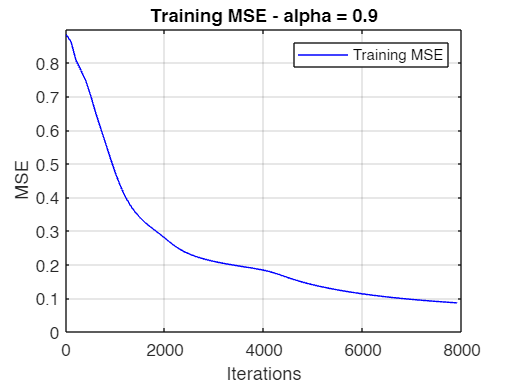

%learning rate
alpha = 0.9;

%randomly initalize weight(Theta) between (-t, t)
t = 0.5;
Theta1 = rand(num_layer2, num_layer1+1)*t*2 - t;
Theta2 = rand(num_layer3, num_layer2+1)*t*2 - t;

%model training
%create an empty array for visualization of error(MSE-mean square error)
MSE_all= [];

for i = 1:max_iteration
    %feedforward
    %from layer 1 to layer 2
    z2 = X_train_bias * Theta1';
    a2 = sigmoid(z2); 

    %from layer 2 to layer 3
    one_col = ones(size(a2, 1), 1); 
    a2_bias = [one_col, a2];
    z3 = a2_bias * Theta2';
    a3 = sigmoid(z3);

    %backpropagation
    %layer3
    Detrivate_g_z3 = a3.*(ones(size(a3))-a3);
    s3 = (a3 - Y_train).*Detrivate_g_z3;
    %layer2
    Detrivate_g_z2 = a2.*(ones(size(a2))-a2);
    s2 = (s3*Theta2(:,2:end)).*Detrivate_g_z2;
    
    %compute partial derivatives for update the weight(Theta)
    Delta2 = zeros(num_layer3, num_layer2+1);
    Delta1 = zeros(num_layer2, num_layer1+1);
    D_gradient2 = zeros(num_layer3, num_layer2+1);
    D_gradient1 = zeros(num_layer2, num_layer1+1);

    %from layer3 to layer2
    Delta2(:,2:end) = Delta2(:,2:end) + s3'*a2;
    Delta2(:,1) = Delta2(:,1) + (s3(1,:))';
    %from layer2 to layer1
    Delta1(:,2:end) = Delta1(:,2:end) + s2'*X_train;
    Delta1(:,1) = Delta1(:,1) + (s2(1,:))';
    
    %add regularization term to partial derivatives, but not on the bias term 
    %from layer3 to layer2
    D_gradient2(:,2:end) = (1/size(X_train,1))*(Delta2(:,2:end) + (lambda*Theta2(:,2:end)));
    D_gradient2(:,1) = (1/size(X_train,1)).*Delta2(:,1);
    %from layer2 to layer1
    D_gradient1(:,2:end) = (1/size(X_train,1))*(Delta1(:,2:end) + (lambda*Theta1(:,2:end)));
    D_gradient1(:,1) = (1/size(X_train,1))*Delta1(:,1);
    
    %update the weight(Theta) between layers
    Theta2 = Theta2 - alpha*D_gradient2;
    Theta1 = Theta1 - alpha*D_gradient1;

    %moniter the error between hypothesis and expected output every 100 iterations
    evaluation_interval = 100;
    if mod(i, evaluation_interval) == 0
        %compute MSE
        MSE = (1/size(Y_train, 1))*sum(sum((a3-Y_train).^2));
        %store the MSE for plot later
        MSE_all = [MSE_all, MSE];
    end
end

%plot the tendency of MSE
iterations = 1:evaluation_interval:max_iteration; %set X
figure;
plot(iterations, MSE_all, 'b', 'DisplayName', 'Training MSE');
title('Training MSE - alpha = 0.9');
xlabel('Iterations');
ylabel('MSE');
legend;
grid on;



%test the examples

%feedforward
%layer1 to layer2
z2 = X_test_bias * Theta1';
a2 = sigmoid(z2);
%layer2 to layer3
one_col = ones(size(a2, 1), 1);
a2_bias = [one_col, a2];
z3 = a2_bias * Theta2';
a3 = sigmoid(z3);

%convert probability into binary results
output_labels = a3 >= threshold

output_labels = 8×8 logical array
   0   0   0   0   0   0   1   0
   0   0   1   0   0   0   0   0
   1   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   0
   0   0   0   0   0   0   0   1
   0   0   0   0   0   1   0   0
   0   1   0   0   0   0   0   0
   0   0   0   1   0   0   0   0



%measure the accuracy
sum_total = size(X_test, 1);
m = all(X_test == output_labels, 2);
rowMatches = sum(m)

rowMatches = 8

accuracy = rowMatches/sum_total

accuracy = 1

#### 2.1.3 Numbers of iteration (batch gradient descent)

#### max_iteration = 1000

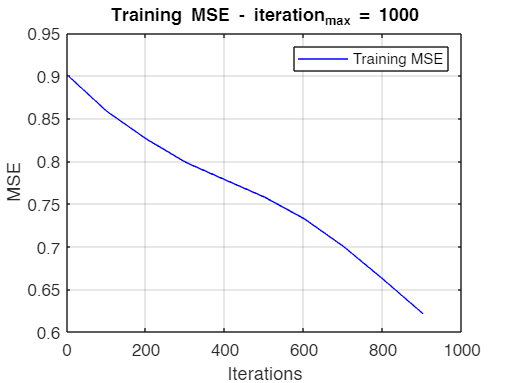

%iteration for model to converge
max_iteration = 1000; 

%reset learning rate
alpha = 0.5;

%randomly initalize weight(Theta) between (-t, t)
t = 0.5;
Theta1 = rand(num_layer2, num_layer1+1)*t*2 - t;
Theta2 = rand(num_layer3, num_layer2+1)*t*2 - t;

%model training
%create an empty array for visualization of error(MSE-mean square error)
MSE_all= [];

for i = 1:max_iteration
    %feedforward
    %from layer 1 to layer 2
    z2 = X_train_bias * Theta1';
    a2 = sigmoid(z2); 

    %from layer 2 to layer 3
    one_col = ones(size(a2, 1), 1); 
    a2_bias = [one_col, a2];
    z3 = a2_bias * Theta2';
    a3 = sigmoid(z3);

    %backpropagation
    %layer3
    Detrivate_g_z3 = a3.*(ones(size(a3))-a3);
    s3 = (a3 - Y_train).*Detrivate_g_z3;
    %layer2
    Detrivate_g_z2 = a2.*(ones(size(a2))-a2);
    s2 = (s3*Theta2(:,2:end)).*Detrivate_g_z2;
    
    %compute partial derivatives for update the weight(Theta)
    Delta2 = zeros(num_layer3, num_layer2+1);
    Delta1 = zeros(num_layer2, num_layer1+1);
    D_gradient2 = zeros(num_layer3, num_layer2+1);
    D_gradient1 = zeros(num_layer2, num_layer1+1);

    %from layer3 to layer2
    Delta2(:,2:end) = Delta2(:,2:end) + s3'*a2;
    Delta2(:,1) = Delta2(:,1) + (s3(1,:))';
    %from layer2 to layer1
    Delta1(:,2:end) = Delta1(:,2:end) + s2'*X_train;
    Delta1(:,1) = Delta1(:,1) + (s2(1,:))';
    
    %add regularization term to partial derivatives, but not on the bias term 
    %from layer3 to layer2
    D_gradient2(:,2:end) = (1/size(X_train,1))*(Delta2(:,2:end) + (lambda*Theta2(:,2:end)));
    D_gradient2(:,1) = (1/size(X_train,1)).*Delta2(:,1);
    %from layer2 to layer1
    D_gradient1(:,2:end) = (1/size(X_train,1))*(Delta1(:,2:end) + (lambda*Theta1(:,2:end)));
    D_gradient1(:,1) = (1/size(X_train,1))*Delta1(:,1);
    
    %update the weight(Theta) between layers
    Theta2 = Theta2 - alpha*D_gradient2;
    Theta1 = Theta1 - alpha*D_gradient1;

    %moniter the error between hypothesis and expected output every 100 iterations
    evaluation_interval = 100;
    if mod(i, evaluation_interval) == 0
        %compute MSE
        MSE = (1/size(Y_train, 1))*sum(sum((a3-Y_train).^2));
        %store the MSE for plot later
        MSE_all = [MSE_all, MSE];
    end
end

%plot the tendency of MSE
iterations = 1:evaluation_interval:max_iteration; %set X
figure;
plot(iterations, MSE_all, 'b', 'DisplayName', 'Training MSE');
title('Training MSE - iteration_max = 1000');
xlabel('Iterations');
ylabel('MSE');
legend;
grid on;



%test the examples

%feedforward
%layer1 to layer2
z2 = X_test_bias * Theta1';
a2 = sigmoid(z2);
%layer2 to layer3
one_col = ones(size(a2, 1), 1);
a2_bias = [one_col, a2];
z3 = a2_bias * Theta2';
a3 = sigmoid(z3);

%convert probability into binary results
output_labels = a3 >= threshold

output_labels = 8×8 logical array
   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



%measure the accuracy
sum_total = size(X_test, 1);
m = all(X_test == output_labels, 2);
rowMatches = sum(m)

rowMatches = 2

accuracy = rowMatches/sum_total

accuracy = 0.2500

#### max_iteration = 5000

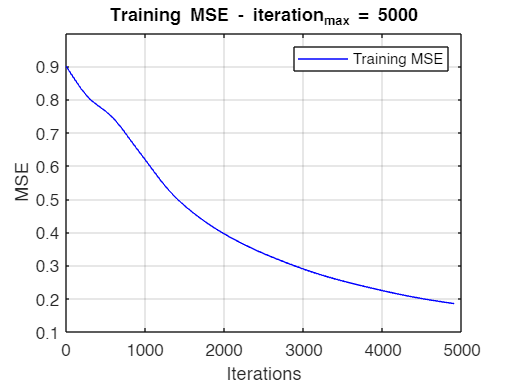

%iteration for model to converge
max_iteration = 5000; 

%randomly initalize weight(Theta) between (-t, t)
t = 0.5;
Theta1 = rand(num_layer2, num_layer1+1)*t*2 - t;
Theta2 = rand(num_layer3, num_layer2+1)*t*2 - t;

%model training
%create an empty array for visualization of error(MSE-mean square error)
MSE_all= [];

for i = 1:max_iteration
    %feedforward
    %from layer 1 to layer 2
    z2 = X_train_bias * Theta1';
    a2 = sigmoid(z2); 

    %from layer 2 to layer 3
    one_col = ones(size(a2, 1), 1); 
    a2_bias = [one_col, a2];
    z3 = a2_bias * Theta2';
    a3 = sigmoid(z3);

    %backpropagation
    %layer3
    Detrivate_g_z3 = a3.*(ones(size(a3))-a3);
    s3 = (a3 - Y_train).*Detrivate_g_z3;
    %layer2
    Detrivate_g_z2 = a2.*(ones(size(a2))-a2);
    s2 = (s3*Theta2(:,2:end)).*Detrivate_g_z2;
    
    %compute partial derivatives for update the weight(Theta)
    Delta2 = zeros(num_layer3, num_layer2+1);
    Delta1 = zeros(num_layer2, num_layer1+1);
    D_gradient2 = zeros(num_layer3, num_layer2+1);
    D_gradient1 = zeros(num_layer2, num_layer1+1);

    %from layer3 to layer2
    Delta2(:,2:end) = Delta2(:,2:end) + s3'*a2;
    Delta2(:,1) = Delta2(:,1) + (s3(1,:))';
    %from layer2 to layer1
    Delta1(:,2:end) = Delta1(:,2:end) + s2'*X_train;
    Delta1(:,1) = Delta1(:,1) + (s2(1,:))';
    
    %add regularization term to partial derivatives, but not on the bias term 
    %from layer3 to layer2
    D_gradient2(:,2:end) = (1/size(X_train,1))*(Delta2(:,2:end) + (lambda*Theta2(:,2:end)));
    D_gradient2(:,1) = (1/size(X_train,1)).*Delta2(:,1);
    %from layer2 to layer1
    D_gradient1(:,2:end) = (1/size(X_train,1))*(Delta1(:,2:end) + (lambda*Theta1(:,2:end)));
    D_gradient1(:,1) = (1/size(X_train,1))*Delta1(:,1);
    
    %update the weight(Theta) between layers
    Theta2 = Theta2 - alpha*D_gradient2;
    Theta1 = Theta1 - alpha*D_gradient1;

    %moniter the error between hypothesis and expected output every 100 iterations
    evaluation_interval = 100;
    if mod(i, evaluation_interval) == 0
        %compute MSE
        MSE = (1/size(Y_train, 1))*sum(sum((a3-Y_train).^2));
        %store the MSE for plot later
        MSE_all = [MSE_all, MSE];
    end
end

%plot the tendency of MSE
iterations = 1:evaluation_interval:max_iteration; %set X
figure;
plot(iterations, MSE_all, 'b', 'DisplayName', 'Training MSE');
title('Training MSE - iteration_max = 5000');
xlabel('Iterations');
ylabel('MSE');
legend;
grid on;



%test the examples

%feedforward
%layer1 to layer2
z2 = X_test_bias * Theta1';
a2 = sigmoid(z2);
%layer2 to layer3
one_col = ones(size(a2, 1), 1);
a2_bias = [one_col, a2];
z3 = a2_bias * Theta2';
a3 = sigmoid(z3);

%convert probability into binary results
output_labels = a3 >= threshold

output_labels = 8×8 logical array
   0   0   0   0   0   0   1   0
   0   0   1   0   0   0   0   0
   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   1
   0   0   0   0   0   1   0   0
   0   1   0   0   0   0   0   0
   0   0   0   1   0   0   0   0



%measure the accuracy
sum_total = size(X_test, 1);
m = all(X_test == output_labels, 2);
rowMatches = sum(m)

rowMatches = 7

accuracy = rowMatches/sum_total

accuracy = 0.8750

#### 2.1.4 Weights Initalization

#### Initialize Theta to zero

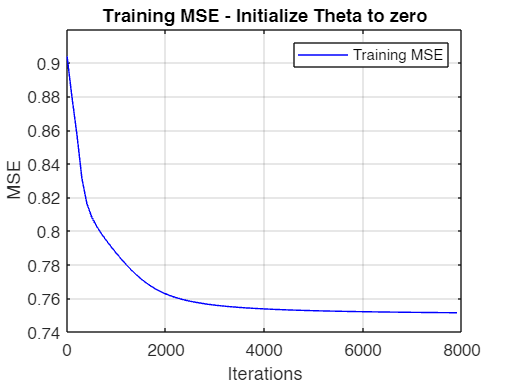

Theta1 = zeros(num_layer2, num_layer1+1);
Theta2 = zeros(num_layer3, num_layer2+1);

%reset iteration for model to converge
max_iteration = 8000; 

%model training
%create an empty array for visualization of error(MSE-mean square error)
MSE_all= [];

for i = 1:max_iteration
    %feedforward
    %from layer 1 to layer 2
    z2 = X_train_bias * Theta1';
    a2 = sigmoid(z2); 

    %from layer 2 to layer 3
    one_col = ones(size(a2, 1), 1); 
    a2_bias = [one_col, a2];
    z3 = a2_bias * Theta2';
    a3 = sigmoid(z3);

    %backpropagation
    %layer3
    Detrivate_g_z3 = a3.*(ones(size(a3))-a3);
    s3 = (a3 - Y_train).*Detrivate_g_z3;
    %layer2
    Detrivate_g_z2 = a2.*(ones(size(a2))-a2);
    s2 = (s3*Theta2(:,2:end)).*Detrivate_g_z2;
    
    %compute partial derivatives for update the weight(Theta)
    Delta2 = zeros(num_layer3, num_layer2+1);
    Delta1 = zeros(num_layer2, num_layer1+1);
    D_gradient2 = zeros(num_layer3, num_layer2+1);
    D_gradient1 = zeros(num_layer2, num_layer1+1);

    %from layer3 to layer2
    Delta2(:,2:end) = Delta2(:,2:end) + s3'*a2;
    Delta2(:,1) = Delta2(:,1) + (s3(1,:))';
    %from layer2 to layer1
    Delta1(:,2:end) = Delta1(:,2:end) + s2'*X_train;
    Delta1(:,1) = Delta1(:,1) + (s2(1,:))';
    
    %add regularization term to partial derivatives, but not on the bias term 
    %from layer3 to layer2
    D_gradient2(:,2:end) = (1/size(X_train,1))*(Delta2(:,2:end) + (lambda*Theta2(:,2:end)));
    D_gradient2(:,1) = (1/size(X_train,1)).*Delta2(:,1);
    %from layer2 to layer1
    D_gradient1(:,2:end) = (1/size(X_train,1))*(Delta1(:,2:end) + (lambda*Theta1(:,2:end)));
    D_gradient1(:,1) = (1/size(X_train,1))*Delta1(:,1);
    
    %update the weight(Theta) between layers
    Theta2 = Theta2 - alpha*D_gradient2;
    Theta1 = Theta1 - alpha*D_gradient1;

    %moniter the error between hypothesis and expected output every 100 iterations
    evaluation_interval = 100;
    if mod(i, evaluation_interval) == 0
        %compute MSE
        MSE = (1/size(Y_train, 1))*sum(sum((a3-Y_train).^2));
        %store the MSE for plot later
        MSE_all = [MSE_all, MSE];
    end
end

%plot the tendency of MSE
iterations = 1:evaluation_interval:max_iteration; %set X
figure;
plot(iterations, MSE_all, 'b', 'DisplayName', 'Training MSE');
title('Training MSE - Initialize Theta to zero');
xlabel('Iterations');
ylabel('MSE');
legend;
grid on;



%test the examples

%feedforward
%layer1 to layer2
z2 = X_test_bias * Theta1';
a2 = sigmoid(z2);
%layer2 to layer3
one_col = ones(size(a2, 1), 1);
a2_bias = [one_col, a2];
z3 = a2_bias * Theta2';
a3 = sigmoid(z3);

%convert probability into binary results
output_labels = a3 >= threshold

output_labels = 8×8 logical array
   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



%measure the accuracy
sum_total = size(X_test, 1);
m = all(X_test == output_labels, 2);
rowMatches = sum(m)

rowMatches = 1

accuracy = rowMatches/sum_total

accuracy = 0.1250

#### Initialize Theta Between (0,1)

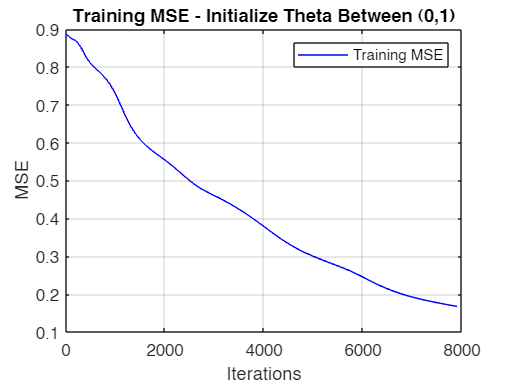

Theta1 = rand(num_layer2, num_layer1+1);
Theta2 = rand(num_layer3, num_layer2+1);

%model training
%create an empty array for visualization of error(MSE-mean square error)
MSE_all= [];

for i = 1:max_iteration
    %feedforward
    %from layer 1 to layer 2
    z2 = X_train_bias * Theta1';
    a2 = sigmoid(z2); 

    %from layer 2 to layer 3
    one_col = ones(size(a2, 1), 1); 
    a2_bias = [one_col, a2];
    z3 = a2_bias * Theta2';
    a3 = sigmoid(z3);

    %backpropagation
    %layer3
    Detrivate_g_z3 = a3.*(ones(size(a3))-a3);
    s3 = (a3 - Y_train).*Detrivate_g_z3;
    %layer2
    Detrivate_g_z2 = a2.*(ones(size(a2))-a2);
    s2 = (s3*Theta2(:,2:end)).*Detrivate_g_z2;
    
    %compute partial derivatives for update the weight(Theta)
    Delta2 = zeros(num_layer3, num_layer2+1);
    Delta1 = zeros(num_layer2, num_layer1+1);
    D_gradient2 = zeros(num_layer3, num_layer2+1);
    D_gradient1 = zeros(num_layer2, num_layer1+1);

    %from layer3 to layer2
    Delta2(:,2:end) = Delta2(:,2:end) + s3'*a2;
    Delta2(:,1) = Delta2(:,1) + (s3(1,:))';
    %from layer2 to layer1
    Delta1(:,2:end) = Delta1(:,2:end) + s2'*X_train;
    Delta1(:,1) = Delta1(:,1) + (s2(1,:))';
    
    %add regularization term to partial derivatives, but not on the bias term 
    %from layer3 to layer2
    D_gradient2(:,2:end) = (1/size(X_train,1))*(Delta2(:,2:end) + (lambda*Theta2(:,2:end)));
    D_gradient2(:,1) = (1/size(X_train,1)).*Delta2(:,1);
    %from layer2 to layer1
    D_gradient1(:,2:end) = (1/size(X_train,1))*(Delta1(:,2:end) + (lambda*Theta1(:,2:end)));
    D_gradient1(:,1) = (1/size(X_train,1))*Delta1(:,1);
    
    %update the weight(Theta) between layers
    Theta2 = Theta2 - alpha*D_gradient2;
    Theta1 = Theta1 - alpha*D_gradient1;

    %moniter the error between hypothesis and expected output every 100 iterations
    evaluation_interval = 100;
    if mod(i, evaluation_interval) == 0
        %compute MSE
        MSE = (1/size(Y_train, 1))*sum(sum((a3-Y_train).^2));
        %store the MSE for plot later
        MSE_all = [MSE_all, MSE];
    end
end

%plot the tendency of MSE
iterations = 1:evaluation_interval:max_iteration; %set X
figure;
plot(iterations, MSE_all, 'b', 'DisplayName', 'Training MSE');
title('Training MSE - Initialize Theta Between (0,1)');
xlabel('Iterations');
ylabel('MSE');
legend;
grid on;



%test the examples

%feedforward
%layer1 to layer2
z2 = X_test_bias * Theta1';
a2 = sigmoid(z2);
%layer2 to layer3
one_col = ones(size(a2, 1), 1);
a2_bias = [one_col, a2];
z3 = a2_bias * Theta2';
a3 = sigmoid(z3);

%convert probability into binary results
output_labels = a3 >= threshold

output_labels = 8×8 logical array
   0   0   0   0   0   0   1   0
   0   0   1   0   0   0   0   0
   1   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   0
   0   0   0   0   0   0   0   1
   0   0   0   0   0   1   0   0
   0   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   0



%measure the accuracy
sum_total = size(X_test, 1);
m = all(X_test == output_labels, 2);
rowMatches = sum(m)

rowMatches = 7

accuracy = rowMatches/sum_total

accuracy = 0.8750

### 2.2 New Data generation

#### 2.2.1 Less Than 8 Example

%prepare training data
X_train = X_train(1:7,:)

X_train =      0     0     0     0     0     0     1     0
     0     0     0     1     0     0     0     0
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     1
     0     0     1     0     0     0     0     0


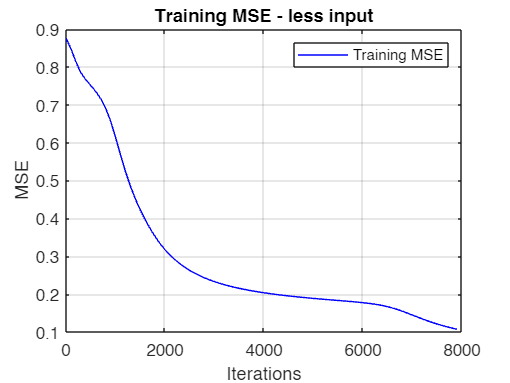

Y_train = X_train;
%add the bias term for input layer
one_col = ones(size(X_train, 1), 1);
X_train_bias = [one_col, X_train];

%randomly initalize weight(Theta) between (-t, t)
t = 0.5;
Theta1 = rand(num_layer2, num_layer1+1)*t*2 - t;
Theta2 = rand(num_layer3, num_layer2+1)*t*2 - t;

%model training
%create an empty array for visualization of error(MSE-mean square error)
MSE_all= [];

for i = 1:max_iteration
    %feedforward
    %from layer 1 to layer 2
    z2 = X_train_bias * Theta1';
    a2 = sigmoid(z2); 

    %from layer 2 to layer 3
    one_col = ones(size(a2, 1), 1); 
    a2_bias = [one_col, a2];
    z3 = a2_bias * Theta2';
    a3 = sigmoid(z3);

    %backpropagation
    %layer3
    Detrivate_g_z3 = a3.*(ones(size(a3))-a3);
    s3 = (a3 - Y_train).*Detrivate_g_z3;
    %layer2
    Detrivate_g_z2 = a2.*(ones(size(a2))-a2);
    s2 = (s3*Theta2(:,2:end)).*Detrivate_g_z2;
    
    %compute partial derivatives for update the weight(Theta)
    Delta2 = zeros(num_layer3, num_layer2+1);
    Delta1 = zeros(num_layer2, num_layer1+1);
    D_gradient2 = zeros(num_layer3, num_layer2+1);
    D_gradient1 = zeros(num_layer2, num_layer1+1);

    %from layer3 to layer2
    Delta2(:,2:end) = Delta2(:,2:end) + s3'*a2;
    Delta2(:,1) = Delta2(:,1) + (s3(1,:))';
    %from layer2 to layer1
    Delta1(:,2:end) = Delta1(:,2:end) + s2'*X_train;
    Delta1(:,1) = Delta1(:,1) + (s2(1,:))';
    
    %add regularization term to partial derivatives, but not on the bias term 
    %from layer3 to layer2
    D_gradient2(:,2:end) = (1/size(X_train,1))*(Delta2(:,2:end) + (lambda*Theta2(:,2:end)));
    D_gradient2(:,1) = (1/size(X_train,1)).*Delta2(:,1);
    %from layer2 to layer1
    D_gradient1(:,2:end) = (1/size(X_train,1))*(Delta1(:,2:end) + (lambda*Theta1(:,2:end)));
    D_gradient1(:,1) = (1/size(X_train,1))*Delta1(:,1);
    
    %update the weight(Theta) between layers
    Theta2 = Theta2 - alpha*D_gradient2;
    Theta1 = Theta1 - alpha*D_gradient1;

    %moniter the error between hypothesis and expected output every 100 iterations
    evaluation_interval = 100;
    if mod(i, evaluation_interval) == 0
        %compute MSE
        MSE = (1/size(Y_train, 1))*sum(sum((a3-Y_train).^2));
        %store the MSE for plot later
        MSE_all = [MSE_all, MSE];
    end
end

%plot the tendency of MSE
iterations = 1:evaluation_interval:max_iteration; %set X
figure;
plot(iterations, MSE_all, 'b', 'DisplayName', 'Training MSE');
title('Training MSE - less input');
xlabel('Iterations');
ylabel('MSE');
legend;
grid on;



%test the examples

%feedforward
%layer1 to layer2
z2 = X_test_bias * Theta1';
a2 = sigmoid(z2);
%layer2 to layer3
one_col = ones(size(a2, 1), 1);
a2_bias = [one_col, a2];
z3 = a2_bias * Theta2';
a3 = sigmoid(z3);

%convert probability into binary results
output_labels = a3 >= threshold

output_labels = 8×8 logical array
   0   0   0   0   0   0   1   0
   0   0   1   0   0   0   0   0
   1   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   0
   0   0   0   0   0   0   0   1
   0   0   0   0   0   0   1   0
   0   1   0   0   0   0   0   0
   0   0   0   1   0   0   0   0



%measure the accuracy
sum_total = size(X_test, 1);
m = all(X_test == output_labels, 2);
rowMatches = sum(m)

rowMatches = 7

accuracy = rowMatches/sum_total

accuracy = 0.8750

#### 2.2.2 Add More Binary Data

%generate more 1 from given examples 
n = 8;  
X_new = dec2bin(0:2^n-1, n) - '0';

%number of new dataset
total_rows= 2^n;

%generate a random permutation of row indices
permuted_indices = randperm(total_rows);
X_train = X_new(permuted_indices,:)

X_train =      0     1     0     1     0     0     1     0
     0     0     0     0     1     1     0     1
     1     0     1     1     0     0     0     1
     0     1     0     1     0     1     0     0
     0     0     0     1     0     1     1     1
     1     0     0     1     0     0     1     1
     0     1     1     1     0     0     1     1
     0     0     0     1     1     0     1     1
     0     0     0     1     1     1     0     1
     1     1     0     1     0     0     1     1


Y_train = X_train;

%add the bias term for input layer
one_col = ones(size(X_train, 1), 1);
X_train_bias = [one_col, X_train];

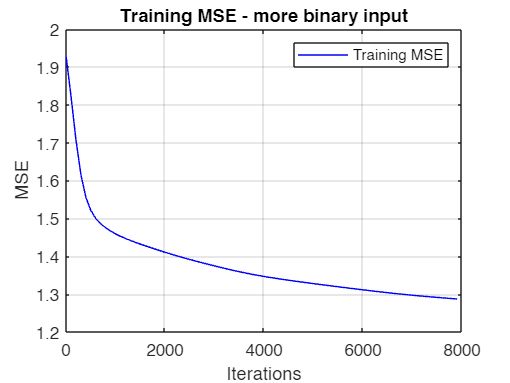

%randomly initalize weight(Theta) between (-t, t)
t = 0.5;
Theta1 = rand(num_layer2, num_layer1+1)*t*2 - t;
Theta2 = rand(num_layer3, num_layer2+1)*t*2 - t;

%model training
%create an empty array for visualization of error(MSE-mean square error)
MSE_all= [];

for i = 1:max_iteration
    %feedforward
    %from layer 1 to layer 2
    z2 = X_train_bias * Theta1';
    a2 = sigmoid(z2); 

    %from layer 2 to layer 3
    one_col = ones(size(a2, 1), 1); 
    a2_bias = [one_col, a2];
    z3 = a2_bias * Theta2';
    a3 = sigmoid(z3);

    %backpropagation
    %layer3
    Detrivate_g_z3 = a3.*(ones(size(a3))-a3);
    s3 = (a3 - Y_train).*Detrivate_g_z3;
    %layer2
    Detrivate_g_z2 = a2.*(ones(size(a2))-a2);
    s2 = (s3*Theta2(:,2:end)).*Detrivate_g_z2;
    
    %compute partial derivatives for update the weight(Theta)
    Delta2 = zeros(num_layer3, num_layer2+1);
    Delta1 = zeros(num_layer2, num_layer1+1);
    D_gradient2 = zeros(num_layer3, num_layer2+1);
    D_gradient1 = zeros(num_layer2, num_layer1+1);

    %from layer3 to layer2
    Delta2(:,2:end) = Delta2(:,2:end) + s3'*a2;
    Delta2(:,1) = Delta2(:,1) + (s3(1,:))';
    %from layer2 to layer1
    Delta1(:,2:end) = Delta1(:,2:end) + s2'*X_train;
    Delta1(:,1) = Delta1(:,1) + (s2(1,:))';
    
    %add regularization term to partial derivatives, but not on the bias term 
    %from layer3 to layer2
    D_gradient2(:,2:end) = (1/size(X_train,1))*(Delta2(:,2:end) + (lambda*Theta2(:,2:end)));
    D_gradient2(:,1) = (1/size(X_train,1)).*Delta2(:,1);
    %from layer2 to layer1
    D_gradient1(:,2:end) = (1/size(X_train,1))*(Delta1(:,2:end) + (lambda*Theta1(:,2:end)));
    D_gradient1(:,1) = (1/size(X_train,1))*Delta1(:,1);
    
    %update the weight(Theta) between layers
    Theta2 = Theta2 - alpha*D_gradient2;
    Theta1 = Theta1 - alpha*D_gradient1;

    %moniter the error between hypothesis and expected output every 100 iterations
    evaluation_interval = 100;
    if mod(i, evaluation_interval) == 0
        %compute MSE
        MSE = (1/size(Y_train, 1))*sum(sum((a3-Y_train).^2));
        %store the MSE for plot later
        MSE_all = [MSE_all, MSE];
    end
end

%plot the tendency of MSE
iterations = 1:evaluation_interval:max_iteration; %set X
figure;
plot(iterations, MSE_all, 'b', 'DisplayName', 'Training MSE');
title('Training MSE - more binary input');
xlabel('Iterations');
ylabel('MSE');
legend;
grid on;



%test the examples

%feedforward
%layer1 to layer2
z2 = X_test_bias * Theta1';
a2 = sigmoid(z2);
%layer2 to layer3
one_col = ones(size(a2, 1), 1);
a2_bias = [one_col, a2];
z3 = a2_bias * Theta2';
a3 = sigmoid(z3)

a3 =     0.3029    0.6345    0.3836    0.6698    0.2442    0.3481    0.6463    0.3697
    0.5535    0.6027    0.9489    0.4209    0.4505    0.0812    0.2836    0.2230
    0.8988    0.4368    0.8582    0.3451    0.0298    0.5774    0.3177    0.3987
    0.2137    0.4791    0.6263    0.4396    0.9937    0.2040    0.4123    0.4855
    0.5172    0.4443    0.3958    0.4794    0.6654    0.6155    0.5186    0.5537
    0.7949    0.3491    0.2770    0.4244    0.1837    0.8892    0.5306    0.6628
    0.3083    0.7224    0.7514    0.6682    0.1177    0.1100    0.5504    0.2090
    0.2840    0.6838    0.5236    0.6853    0.1722    0.2186    0.6238    0.2907



%convert probability into binary results
output_labels = a3 >= threshold

output_labels = 8×8 logical array
   0   1   0   1   0   0   1   0
   1   1   1   0   0   0   0   0
   1   0   1   0   0   1   0   0
   0   0   1   0   1   0   0   0
   1   0   0   0   1   1   1   1
   1   0   0   0   0   1   1   1
   0   1   1   1   0   0   1   0
   0   1   1   1   0   0   1   0



%measure the accuracy
sum_total = size(X_test, 1);
m = all(X_test == output_labels, 2);
rowMatches = sum(m)

rowMatches = 0

accuracy = rowMatches/sum_total

accuracy = 0